#### BME 4400 Vanderbilt University

#### Professor Mark D. Does

# A1 Solutions

clear all
close all
clc

% colorblind friendly colors
black = [0 0 0];
wht = [1 1 1];
orange = [0.9 0.6 0];
skyblue = [0.35 0.7 0.9];
bluegreen = [0 0.6 0.5];
yellow = [.95 .90 .25];
blue = [0 .45 .70];
vermillion = [.8 .4 0];
redpurp = [.8 .6 .7];
gr = [0.5 0.5 0.5];

## Create .mat file for question 1

This section of code was used to create the .mat file for the assignment. If you're just interested in the assignment problem solutions, you can skips this section.

Create sample blurry image -- only need to be run once to save the `IMG1N` image

make_mat_file = false; % Set this to 'true' to write a new A1images.mat file

Ni = 256; % image size in pixels
Nf = 3; % filter size in pixels
IMG1 = imfilter(phantom(Ni),ones(Nf,Nf)/Nf^2);

MATLAB's `phantom` function creates an image of the Shepp Logan phantom, and variations thereof. The `imfilter` function returns the **convolution **of the first and second inputs. A `ones(3,3)/9` filter is simply a **3 x 3 moving average filter** -- each pixel value is replaced by the** average value of the 9 pixels** in the 3 x 3 immediate neighborhood.

imagesc(IMG1); colorbar, colormap(gray)
title('IMG1')
axis off, axis equal
a1 = annotation('textarrow',[0.3,0.45],[0.8,0.65],...
  'Color',orange, 'String','Tissue A','FontSize',12);
a2 = annotation('textarrow',[0.3,0.4],[0.2,0.30],...
  'Color',orange, 'String','Tissue A','FontSize',12);

Note that by defining a handle for objects in a figure, you can easily** edit the object later** because all its features are de**fined by fields in the handl**e. For example, to change the text associated with the second arrow, do this:

a2.String = 'Tissue B';

I'll print a copy that I can insert into the assignment 1 document.

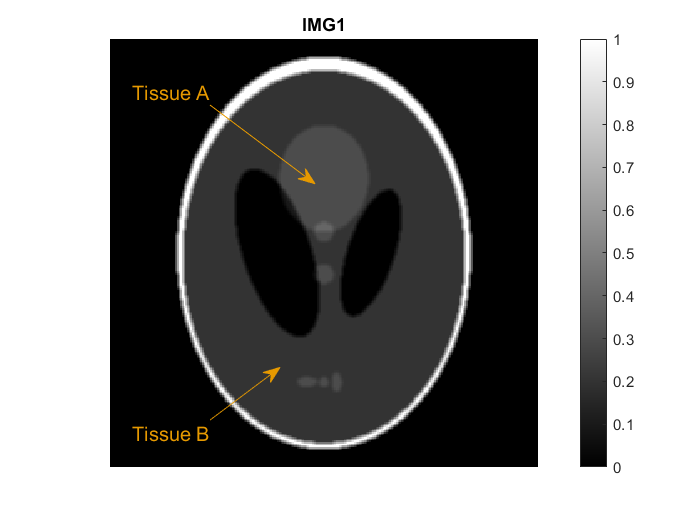

print -dpng IMG1

Then I'll create noise and add it to the image at varying levels. I know the intensity in Tissue B in the phantom image is **0.2**, and I'll define SNR in this region.

SNRspace = logspace(0,log10(500),15); % varying SNR from .1 to 500 - 15 steps
mean_signal_B = 0.2; % signal in Tissue B is 0.2

Define $SNR = \frac{\text{mean}}{\text{standard deviation}}$

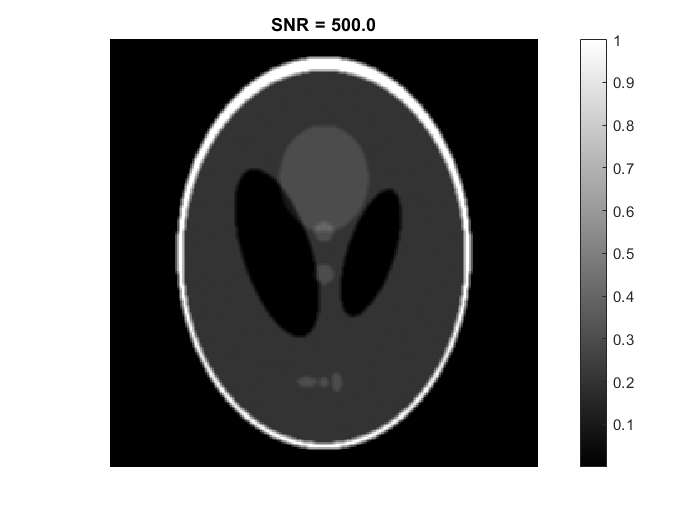

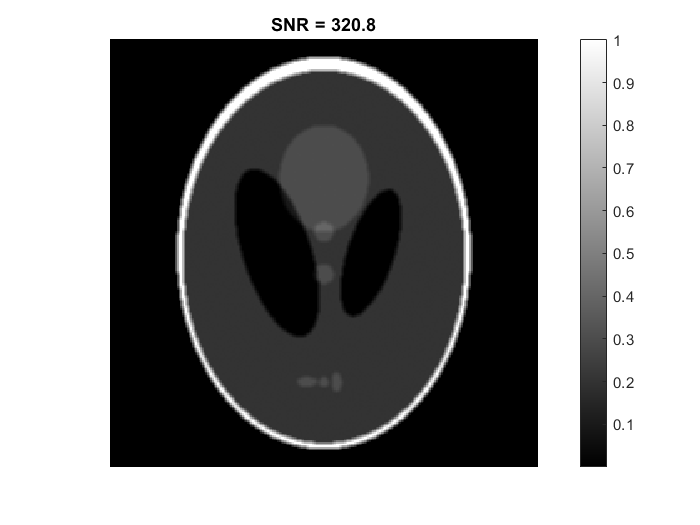

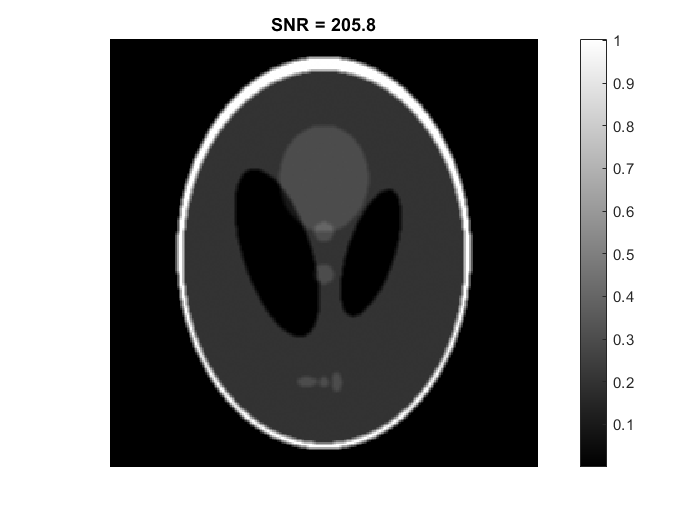

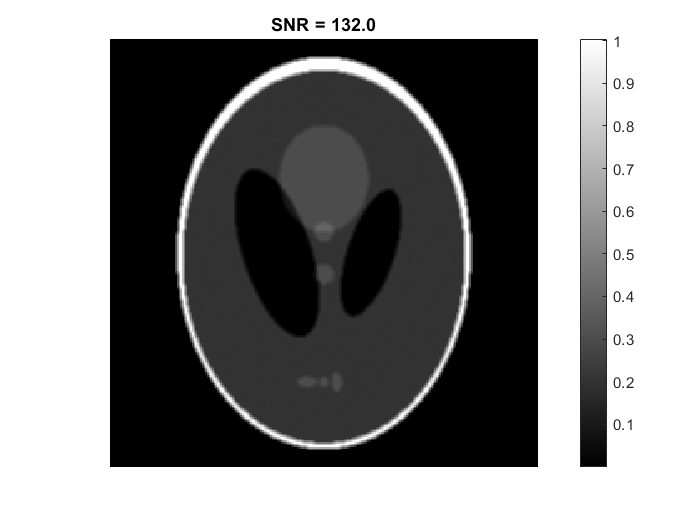

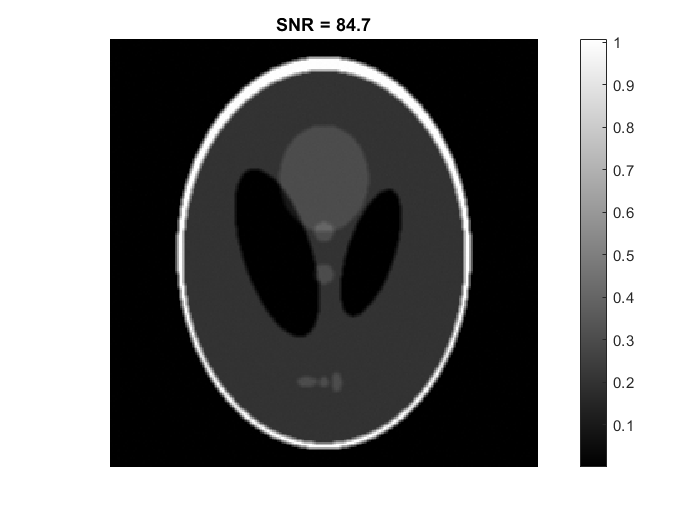

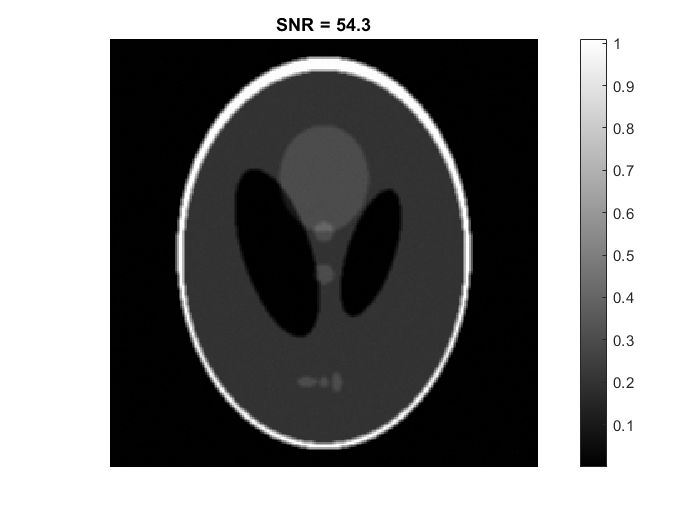

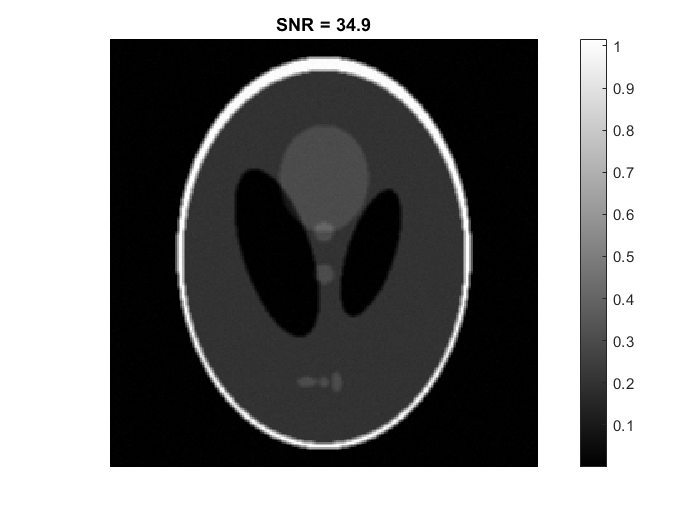

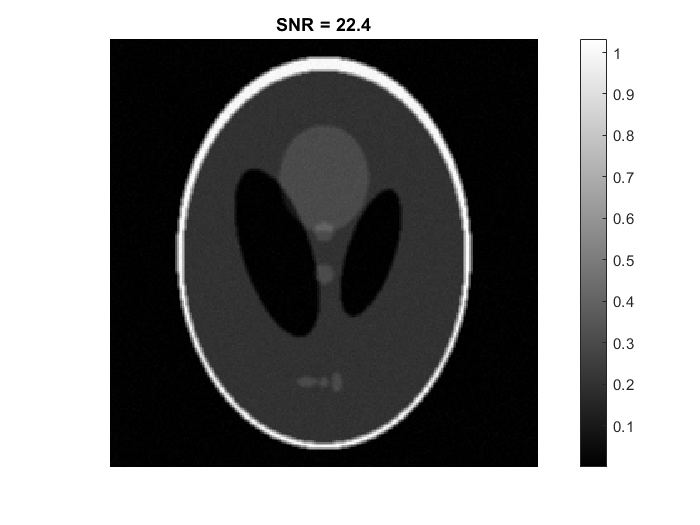

sd_noise = mean_signal_B./SNRspace; % SD of noise to add to make SNR (signal Tissue B/noise)

Ny = size(IMG1,1);
Nx = size(IMG1,2);
Ns = length(SNRspace);
for k = Ns:-1:1
  IMG1N(:,:,k) = abs(IMG1+random('Normal',0,sd_noise(k),size(IMG1)));
  figure(k)
  imagesc(IMG1N(:,:,k)), colorbar, axis('equal'), axis('off'), colormap(gray)
  title(['SNR = ',num2str(SNRspace(k),'%3.1f')])
end

if (make_mat_file)
  save 'A1images' IMG1N
end

## Q2 create; add pebble image to A1images

  clear all
  close all
  clc
  X = double(rgb2gray(imread('pebbles.jpg')))./255;

Error using imread>get_full_filename
File "pebbles.jpg" does not exist.

Error in imread (line 371)
    fullname = get_full_filename(filename);

  IMG2 = X(250:549,401:800);

if(make_mat_file)
  save 'A1images' IMG2 -append
end

## Solutions 1a and 1b

clear all, close all
load A1images
Ni = size(IMG1N,3); % number of images -- should equal 15


You may need to look into the MATLAB help/documentation to learn how to use the `roipoly` function.

% draw ROIs in tissues A, B and the background
imagesc(IMG1N(:,:,Ni)); axis('equal'),axis('off')
title('draw ROI in Tissue A')
roiA = roipoly;
title('draw ROI in Tissue B')
roiB = roipoly;
for k = Ni:-1:1
  X = IMG1N(:,:,k);
  % measure the signal mean and sd from each ROI
  MA = mean(X(roiA));
  SA = std(X(roiA));
  MB = mean(X(roiB));
  SB = std(X(roiB));
  % compute the CNR for each noisy image
  CNR_A_B(k) = abs(MA-MB)./SA;
  % display image and label with CNR
  figure
  colormap('gray')
  imagesc(IMG1N(:,:,k)), colorbar, axis('equal'), axis('off')
  tstring = sprintf('Measured CNR = %0.1f',CNR_A_B(k));
  title(tstring)
end

My ability to distinguish adjacent tissues depends on their contrast (difference in signal magnitudes) AND the size of the structures. At the lowest a CNR (~ 0.4), I can see very little—the ring of signal around the head and I can just barely make out the large circular *Tissue A* region. 

At around twice that CNR (~0.7), I can see all three large structure, but not really any of the small ones. 

At CNR ~ 1.3, the two small circular structures are apparent, but three small ones near the bottom are not.

At CNR ~ 3, all structures are visible, but the three small ones are not entirely clear or distinguishable.

At CNR ~ 4.5, a**ll structures are distinguishable and fairly clear.**

As CNR increases to ~ 17, the images looks sharper, but beyond the differences are hard to see by eye.

The explanation for being able to see large structures is the *mo****dulation transfer function*** of the hypothetical imaging system. Like most systems, it appears to have** a transfer function that rolls off to lower value**s at **higher spatial frequencies.** That is, the system *transfers* low spatial frequency information better than high spatial frequecy information.** Identifying small structures in the image **corresponds to identifying si**gnals at high spatial frequencies, **so these are the first structures to be lost in the noise as the variance of the noise increases.

It is also worth noting that beyond a certain point (CNR ~ 20), our eyes don't seem much improvement, but if we analyzed these images numerically, the statistically ability to distinguish different tissues continues to improve as CNR increases.

## Q2a Solution

%clear all
%close all
%load A1images
X = IMG2;

 Define the point spread functions for each system, as provided in the assignment

h1 = [1 2 1; ...
      2 4 2; ...
      1 2 1]/16;

h2 = ones(3,3)/9;

h3 = -[0 -1 0; ...
      -1 5 -1;...
       0 -1 0];

Use the `conv2` function to perform convolution of input image (`X`) with the PSF of each system. Note that I'm using the `"same"` option in `conv2` to keep the input and output images the same size for convenience

Y1 = abs(conv2(X,h1,'same'));
Y2 = abs(conv2(X,h2,'same'));
Y3 = abs(conv2(X,h3,'same'));

Then use the `imagesc` function to generate images of the original input (`X`) and each of the 3 output images (`Y1`, `Y2`, and `Y3`)

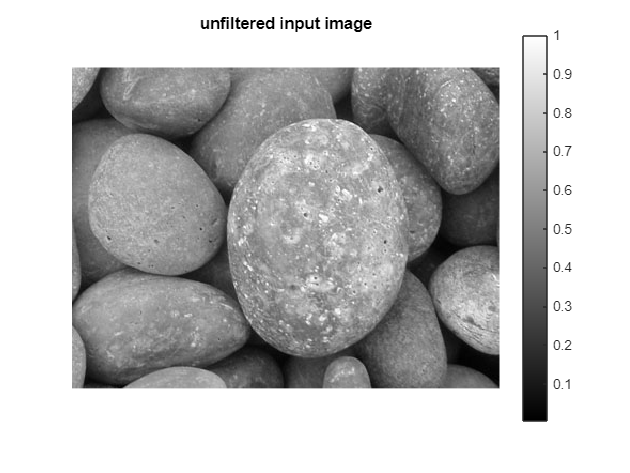

figure
imagesc(X); colormap(gray),colorbar, axis('equal','off')
title('unfiltered input image');

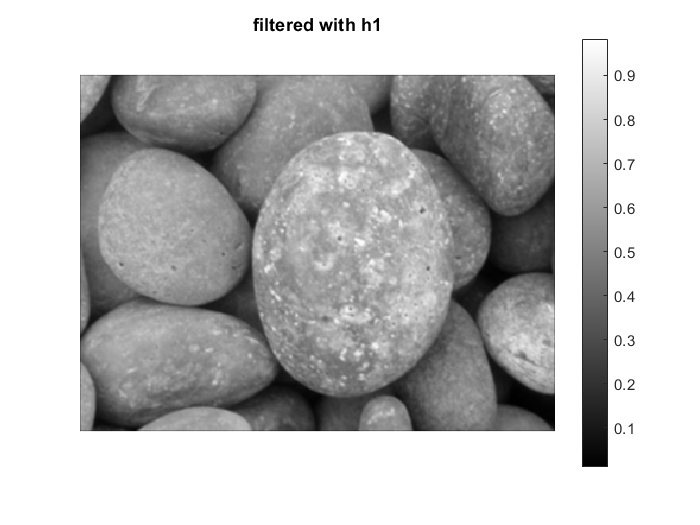

figure
imagesc(Y1); colormap(gray),colorbar, axis('equal','off')
title('filtered with h1');

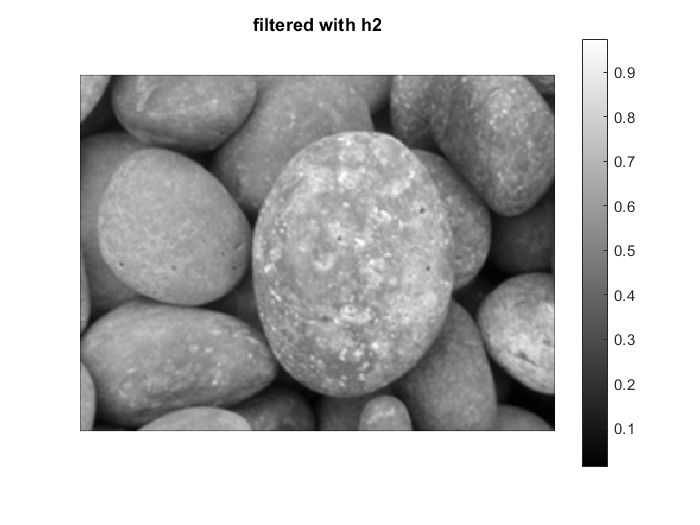

figure
imagesc(Y2); colormap(gray),colorbar, axis('equal','off')
title('filtered with h2');

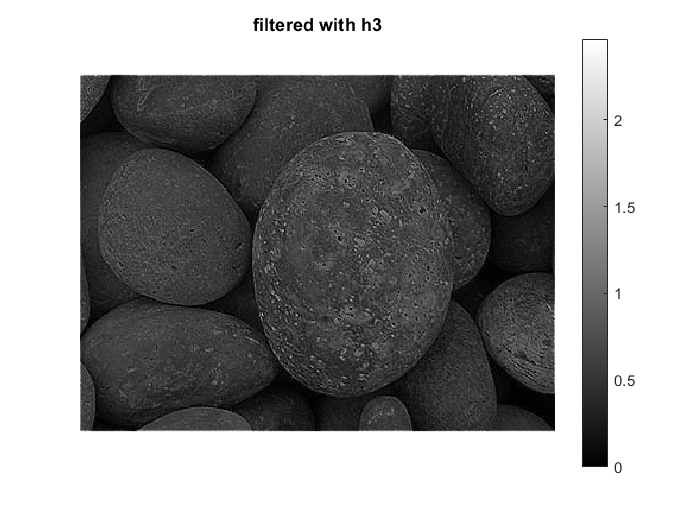

figure
imagesc(Y3); colormap(gray),colorbar, axis('equal','off')
title('filtered with h3');

## 2a Qualitatively describe the effect of each filter

Systems `h1` and `h2` blur the image --- the loss of fine detail is particularly noticeable in the large pepple in the center of the frame. If I look closely in areas of high contrast and sharp features, the image filtered with `h1`** looks a little more well defined **than one filtered with `h2`, meaning that the second fitlter caused a greater degree of blurring.

In contrast, the image filtered with `h3` highlights the fine details on the rocks while darkening the overall image

## 2b Compute and plot the Fourier spectrum of each filter

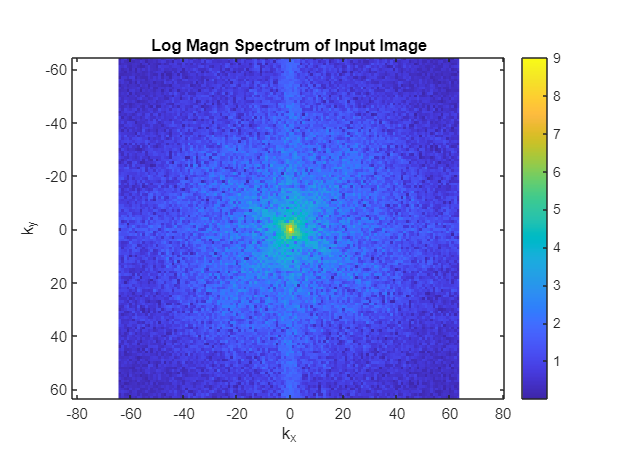

N = 128; % Fourier domain size -- somewhat arbitrary
XF = log(1+abs(fftshift(fft2(X,N,N))));
kindex = (-N/2:(N/2-1));
figure
imagesc(kindex, kindex,XF), axis('equal'), colorbar
xlabel('k_x'), ylabel('k_y')
title('Log Magn Spectrum of Input Image');

As expected, the spectrum of the original image is **unremarkable -- large signal at zero frequency** since the p**ixel intensities are all non-negative,** and the magnitude spectrum is roughly circularly symmetric which is expected since there** no particular orientiation dependence** on the information in the original image.

Now do the same for each filtered image.

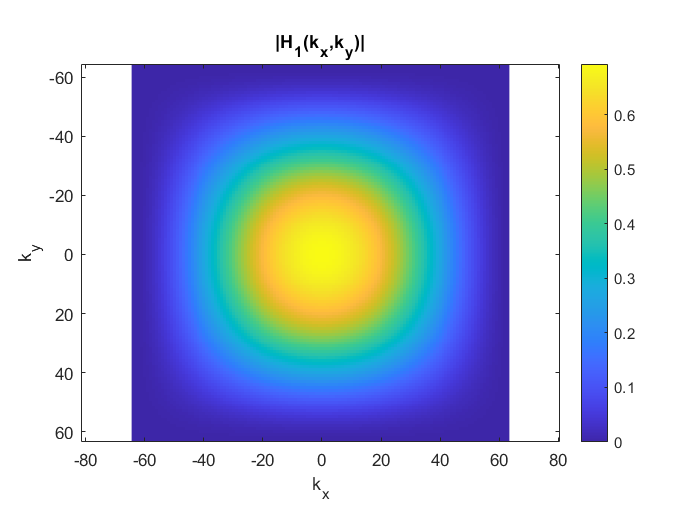

figure
H1 = fftshift(fft2(h1,N,N));
imagesc(kindex, kindex,log(1+abs(H1))), axis('equal'), colorbar
xlabel('k_x'), ylabel('k_y')
title('|H_1(k_x,k_y)|');

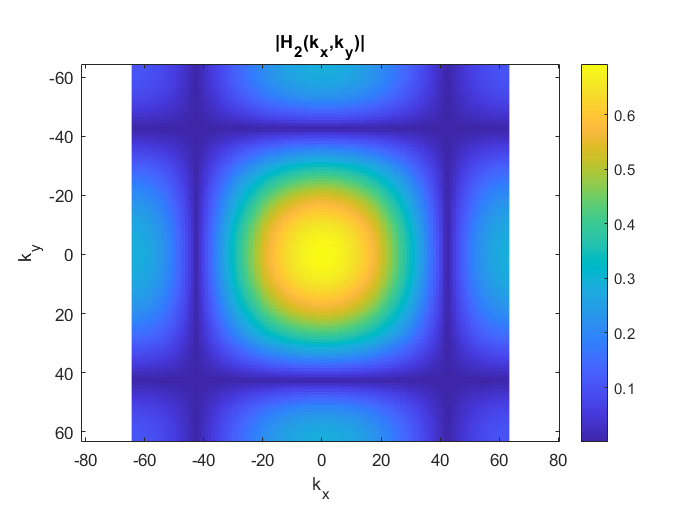


figure
H2 = fftshift(fft2(h2,N,N));
imagesc(kindex, kindex,log(1+abs(H2))), axis('equal'), colorbar
xlabel('k_x'), ylabel('k_y')
title('|H_2(k_x,k_y)|');

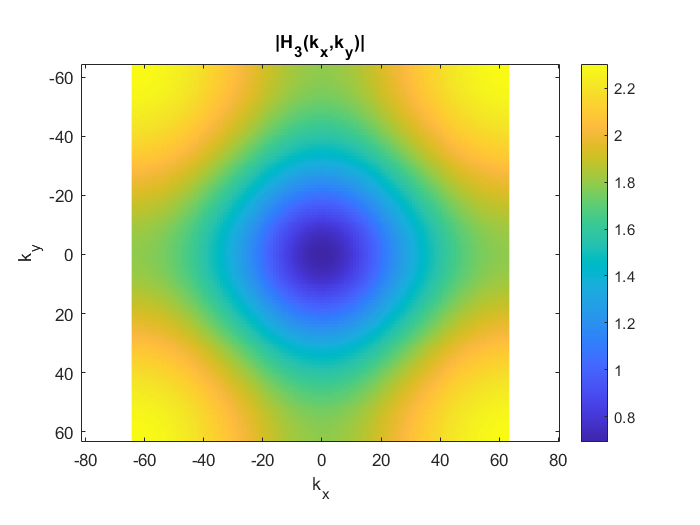

figure
H3 = fftshift(fft2(h3,N,N));
imagesc(kindex, kindex,log(1+abs(H3))), axis('equal'), colorbar
xlabel('k_x'), ylabel('k_y')
title('|H_3(k_x,k_y)|');

We can see that `h1`** is low-pass filter in the freq domain**; hence the blurring. The `h2`** filter is also generally a low-pass, **but it has a null approximately 2/3 of the way between 0 frequency (center) and the max frequency (edge), which slightly increases the effective blurring despite the higer max frequency spectral intensity.

In contrast, the `h3` filter bo**osts signals with high spatial frequencies**, resulting in the highlighting of small image features. If you look carefully, you'll see that the zero frequency component of `H3 `approximately the same as the zero freq component of `H1` and `H2`, so why does the image from `h3` look darker? The answer is simply that the MATLAB imagesc function sets the color scale to span the full dynamic range of pixel intensities. The output of `h3` cotains some pixels that **are brighter than the origina**l, so the most of the image appears at a darker grayscale value.

## 2c

h_identity=[0 0 0;...
            0 1 0; ...
            0 0 0];

This has the identity property because it is a representation of the delta function. Delta functions **select a single point of interes**t and m**ap them directly into the new image **during the process of convolution.

%Proof:
copied_img=conv2(IMG2,h_identity,'same');
if isequal(copied_img,IMG2)
  fprintf('The images are identical')
end

The images are identical

## 2d

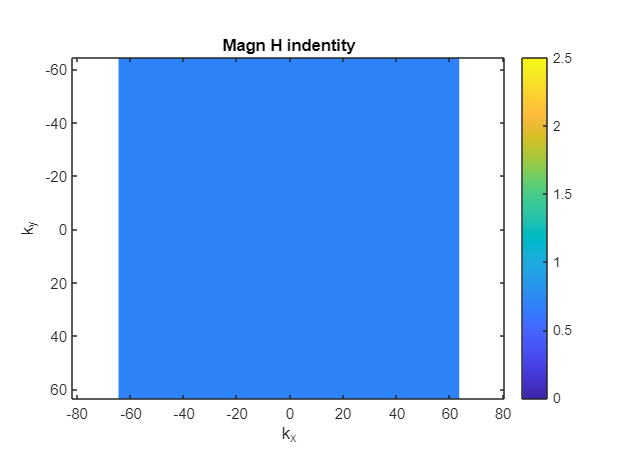

figure
H_indentity = log(1+abs(fftshift(fft2(h_identity,N,N))));
imagesc(kindex, kindex,H_indentity,[0 2.5]), axis('equal'), colorbar
xlabel('k_x'), ylabel('k_y')
title('Magn H indentity');
colorbar

**This is a flat surface of magnitude = 1** (i.e., figure shows uniform intensity $I = 0.69 = \log(1+X)$, therefore $X = exp(0.69)-1 = 1$). This filter will transfer all frequencies equally and without scaling to the new image.

## 3a-c

For these solutions, define $x$ as pointing right across columns/along rows, and $y$ as pointing up across rows/along columns.

3a. To intergrate a local area**, we sum each value in the local area, **mutiplied by the step size (pixel size) in each direction, resulting in a measure in input i**mage intensity units** times **area.**

pix_size = 2; % units mm
h3a = pix_size^2*[1 1 1;
                  1 1 1; 
                  1 1 1];  %result in image units * mm^2

3b. To approximate a derivative in the x-direction, compute the difference in intensities +/- one pixel in the x-direction, divided by the step size (2 pixels). Remember that PSFs are flipped before convolution, so the negative should be on the right before being flipped to the left. 

h3b = [0 0 0;
       1 0 -1;
       0 0 0]/(2*pix_size);
%result in image units per mm.

3c This one is a bit trickier to **directly generate, but if you follow the hin**t, then


$$\frac{\partial^2I}{\partial x\partial y} =\frac{\partial }{\partial y}\frac{\partial I}{\partial x}$$


Given the partial derivative wrt $x$ is computed by $I \ast h_\mathrm{3b}$ , and the partial derivative wrt $y$ is $I \ast h_\mathrm{3b}^\mathrm{T}$, we can conclude that $\frac{\partial^2I}{\partial x\partial y} =I\ast h_\mathrm{3b}\ast h_\mathrm{3b}^\mathrm{T}$

h3c = conv2(h3b,h3b', 'same')

3d Fourier transforms of the filters, using the same Fourier-domain matrix size as before:

figure
H3a = fftshift(fft2(h3a,N,N));
imagesc(kindex,kindex,log(1+abs(H3a))), axis('equal'), colorbar
xlabel('k_x'), ylabel('k_y')
title('|H_{3a}(k_x,k_y)|');
colorbar
figure
H3b = fftshift(fft2(h3b,N,N));
imagesc(kindex,kindex,log(1+abs(H3b))), axis('equal'), colorbar
xlabel('k_x'), ylabel('k_y')
title('|H_{3b}(k_x,k_y)|');
colorbar
figure
H3c = fftshift(fft2(h3c,N,N));
imagesc(kindex,kindex,log(1+abs(H3c))),axis('equal'), colorbar
xlabel('k_x'), ylabel('k_y')
title('|H_{3c}(k_x,k_y)|');
colorbar


The Fourier Transforms of these filters reveals that integral is a low-pass filter (compare `h3a` to `h2`) while the two differential operators are high-pass filters (they remove some signal around $(k_x,k_y) = (0,0)$. Intuitively, the spectrum of `h3b` is unchanging in $y$ while acting like a high-pass filter in $x$. Similarly, h3c suppress all information that is not BOTH high frequency in $x$ AND in $y$. Oblong objects that are short in one dimension and long in the other would be filtered out just as easily as objects that are large in both dimensions.